## Panel B - load data

chanB_fn = 'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 2_170714_007\ChanBfilt.tif';
chanA_fn = 'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 2_170714_007\ChanA.tif';

chanA = loadTif(chanA_fn,8);
chanB = loadTif(chanB_fn,16);
b_dFoF = normalizeImg(chanB,5,1);


## Panel B - Time Series

cropb = b_dFoF(5:508,5:508,:);
cropb = fliplr(cropb);
[h,w] = size(cropb);

stTime = 1678;
time = stTime:5:stTime+7*5;
[m,n] = size(time);
bigImg = zeros(h,h*n);
linex = [1 1 1; h*n  h*n  h*n];
liney = [1 h h;1 h h];
for i=1:n
    bigImg(1:h,1+h*(i-1):h+h*(i-1)) = medfilt2(mean(cropb(:,:,time(i)-1:time(i)+1),3));
    %bigImg(513:1024,1+512*(i-1):512+512*(i-1)) = mean(b_dFoF(:,:,time(i+n/2)-1:time(i+n/2)+1),3);
    linex = [linex [h*(i); h*(i)]];
    liney = [liney [1; h]];
    
end
 figure; imagesc(bigImg); colormap gfb; box off; axis off;
 caxis([-.5 2.5]); line(linex, liney, 'Color', 'w');
 
realTime = (time - stTime)/10;
fs = 8;
for i=1:n
    if i == 1
      text(505,5,sprintf('t = %0.0f s',realTime(i)),'HorizontalAlignment','right','VerticalAlignment','top','FontSize',fs,'Color','w');
    else
      text(h-7+512*(i-1),5,sprintf('%0.1f s',realTime(i)),'HorizontalAlignment','right','VerticalAlignment','top','FontSize',fs,'Color','w');
    end
end
figQuality(gcf,gca,[8 1.1].*3/4)
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2Pexample.eps',gcf);


## Panel B: Green Signal, Magenta Astrocytes Time Series


stTime = 1678;
time = stTime:5:stTime+7*5;
cropImgB = b_dFoF(140:140+127,250:250+127,time(1)-1:time(end)+1);
cropImgA = chanA(140:140+127,250:250+127,time(1)-1:time(end)+1);
cropImgB = imresize(fliplr(cropImgB),4);
cropImgA = imresize(fliplr(cropImgA),4);
[mm,nn] = size(cropImgB);

time = time - time(1)+ 2;
[m,n] = size(time);
bigImg = zeros(mm,mm*n,3);
linex = [1 1 1; mm*n  mm*n  mm*n];
liney = [1 mm mm;1 mm mm];
for i=1:n
    bigImg(1:mm,1+mm*(i-1):mm+mm*(i-1),2) = imgaussfilt((mean(cropImgB(:,:,time(i)-1:time(i)+1),3)./1.5-.15),2);
    bigImg(1:mm,1+mm*(i-1):mm+mm*(i-1),1) = double(cropImgA(:,:,time(i)))./255;
    bigImg(1:mm,1+mm*(i-1):mm+mm*(i-1),3) = double(cropImgA(:,:,time(i)))./255;
    %bigImg(513:1024,1+512*(i-1):512+512*(i-1)) = mean(b_dFoF(:,:,time(i+n/2)-1:time(i+n/2)+1),3);
    linex = [linex [mm*(i); mm*(i)]];
    liney = [liney [1; mm]];
    
end
 figure; imagesc(bigImg); colormap gfb; box off; axis off;
 caxis([-2 3]); line(linex, liney, 'Color', 'w');
 
realTime = (time - stTime)/10;
fs = 8;
for i=1:n
    if i == 1
      text(mm-7,5,sprintf('t = %0.0f s',realTime(i)),'HorizontalAlignment','right','VerticalAlignment','top','FontSize',fs,'Color','w');
    else
      text(mm-7+mm*(i-1),5,sprintf('%0.1f s',realTime(i)),'HorizontalAlignment','right','VerticalAlignment','top','FontSize',fs,'Color','w');
    end
end
figQuality(gcf,gca,[8 1.1]*3/4)
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PexampleMG.eps',gcf);

## ROIs file

imgNorm = normalizeImg(img,10,0);

file = 'M:\Bergles Lab Data\Papers\In Vivo Paper\2p_Figure\first_event_ROIs.mat';
temp = load(file);
ROIs = temp.jmask;
file = 'M:\Bergles Lab Data\Papers\In Vivo Paper\2p_Figure\second_event_ROIs.mat';
temp = load(file);
ROIs = cat(3,ROIs,temp.jmask);
file = 'M:\Bergles Lab Data\Papers\In Vivo Paper\2p_Figure\third_event_ROIs.mat';
temp = load(file);
ROIs = cat(3,ROIs,temp.jmask);

m = size(ROIs,3);
t = size(imgNorm,3);

for i = 1:t
        tempImg = imgNorm(:,:,i);
        for j = 1:m
            ROI = ROIs(:,:,j);
            index = find(ROI);
            ROI_signals(i,j) = mean(tempImg(index))-2*(j-1);
        end
end






## alternative figures

org = [255 155 79]/255;
org_map = [0:1:255; 0:155/255:155; 0:79/255:79]'/256;
green_map = [0:115/255:115; 0:1:255; 0:129/255:129]'/256;
magenta_map = [0:1:255; 0:88/255:88; 0:1:255]'/256;
rain_map = [[255*ones(1,40) 255:-255/19:0 zeros(1,20)  0:255/19:255]/255;...
            [0:255/39:255 255*ones(1,40) 255:-255/19:0]/255;...
            [zeros(1,60) 0:255/19:255 255*ones(1,20)]/255]';



figure;
imagesc(mean(img(:,:,520:540),3));
colormap(org_map);
caxis([50 200]);
axis off;
truesize;
figure;
imagesc(mean(img(:,:,550:570),3));
colormap(green_map);
caxis([25 250]);
axis off;
truesize;
figure;
imagesc(mean(img(:,:,605:635),3));
colormap(magenta_map);
caxis([50 250]);
axis off;
truesize;
figure;
imagesc(mean(img(:,:,2025:2045),3));
colormap(rain_map);
caxis([0 500]);
axis off;
truesize


## Panel C - Neuron/neuropil waveform

files = {'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 1_170714_004\Animal1_2Pevents.mat';
         'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 2_170714_007\Animal2_events.mat';
         'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 3_170720_003\Animal3_events.mat';
         'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 4_170811\Animal4_events.mat';
         'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal5_170815\Animal5events.mat';
        };
    
[m,n] = size(files);

groupAvg = []
for i=1:m
    load(files{i});
    groupAvg = [groupAvg mean(eventsAvg,2)]
    
end
meanNeuron = mean(groupAvg(:,:,1),2);
meanNeuron = meanNeuron - mean(meanNeuron(1:5));
meanNeuropil = mean(groupAvg(:,:,2),2);
meanNeuropil = meanNeuropil - mean(meanNeuropil(1:5));

figure; plot(meanNeuron,'g');
hold on; plot(meanNeuropil,'k');
shadedErrorBar(1:1:131,meanNeuron,std(groupAvg(:,:,1),[],2)/sqrt(5),{'g'})
hold on;
shadedErrorBar(1:1:131,meanNeuropil,std(groupAvg(:,:,2),[],2)/sqrt(5),{'k'})

figure; plot(1:1:131,meanNeuron,'k'); hold on; plot(1:1:131,meanNeuropil,'b');
figQuality(gcf,gca,[2 2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PneunRaw.eps',gcf);

figure; plot(meanNeuron/max(meanNeuron),'k');
hold on; plot(meanNeuropil/max(meanNeuropil),'b');
figQuality(gcf,gca,[2 2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PneunNorm.eps',gcf);


## Panel C - Individual neuron and neuropil signal

files = loadFileList('M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\*\*2PROIs.mat');
load(files{1});
[m,n] = size(Animal1_2PPROIs);
ROIs = reshape(Animal1_2PPROIs,n,1,m);
dFoF = normalizeImg(ROIs,10,1);
dFoF = reshape(dFoF,m,n);

%exponential smoothing for figure
alpha = 0.1;
neuropil = filter(alpha, [1 alpha-1], dFoF(400:1000,5));
neuron = filter(alpha, [1 alpha-1], dFoF(400:1000,6));
time = [1:1:size(neuron,1)]/10;

figure; plot(time, neuron-.08,'k'); %slight baseline subtraction, this was done for the averaging too
hold on; plot(time, neuropil,'b');
ylim([-.05 1]);
xlim([0 time(end)]);
figQuality(gcf,gca,[1.5 .8]);
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PneunSignals.eps',gcf);


%direction plot
list = dir(['M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\*\*direction.mat']);

%example image

imgFile = 'M:\Bergles Lab Data\Projects\In vivo 2P Imaging\Snap25GC6s_SR101\Animal 1_170714_004\ChanBReg_kfilt.tif';
img = loadTif(imgFile,16);

img = normalizeImg(img,10,1);

Bleach correction finished. Subtracting baseline...


i = 1;
fn = [list(i).folder '\' list(i).name];
load(fn);


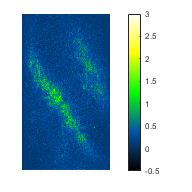


figure;
imagesc(medfilt2(mean(img(:,:,datas.events(5).loc-1:datas.events(5).loc+1),3)));
writeTif(medfilt2(mean(img(:,:,datas.events(5).loc-1:datas.events(5).loc+1),3)),['C:\Users\Bergles Lab\Desktop\example.tif'],32);
box off;
axis off;
colormap gfb; caxis([-.5 3]);
figQuality(gcf,gca,[2 2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PcorrExample.eps',gcf);

colorbar;

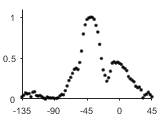


figure;
corrMat = datas.events(5).rotValues(:,2);
angles = datas.events(5).rotValues(:,1);
corrMat = corrMat - min(corrMat);
corrMat = corrMat/max(corrMat);
plot(angles,corrMat,'.','Color','k','MarkerSize',6); hold on;
%plot(angles,corrMat,'Color','k');
ylim([0 1.1]);
yticks([0 0.5 1]);
box off;
xlim([-135 45]);
xticks([-135:45:45]);
figQuality(gcf,gca,[1.75 1.2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PxcorrExample.eps',gcf);


binCounts = [];
for i = 1:size(list,1)
    fn = [list(i).folder '\' list(i).name];
    load(fn);
    angles = [];
    for j = 1:size(datas.events,2)
        if datas.events(j).keep
          angles = [angles; datas.events(j).maxValues(1)];
        end
    end
    
    avgPts = [avgPts; datas.avgPts];
    datas.degrees = angles;
    save(fn,'datas');
    %figure;
    temp = polarhistogram(degtorad(180+datas.degrees),[-3*pi/2-pi/32:pi/16:pi/4+pi/32]);
    binCounts = [binCounts; temp.BinCounts];
    thetaticks([0:45:315]);
    rlim([0 40]);
    rticks([20 40]);
    
end

figure;
i = 1;
fn = [list(i).folder '\' list(i).name];
load(fn); 
%figure;
temp = polarhistogram(degtorad(180+datas.degrees),[-3*pi/2-pi/32:pi/16:pi/4+pi/32],'FaceColor',[0.3 0.3 0.3],'EdgeColor','none','FaceAlpha',1);
rlim([0 40]);
 rticks([20 40]);
 thetaticks([0:45:315]);
 figQuality(gcf,gca,[1.2 1.2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PxcorrInd.eps',gcf);
 
figure;
temp = polarhistogram(degtorad(180+datas.degrees),[-3*pi/2-pi/32:pi/16:pi/4+pi/32],'FaceColor',[0.3 0.3 0.3],'EdgeColor','none','FaceAlpha',1);
temp.BinCounts = mean(binCounts);
thetaticks([0:45:315]);
hold on; 
stdErr = std(binCounts,[],1)/sqrt(5);
midBin = conv(temp.BinEdges,[0.5 0.5]);
midBin = midBin(2:end-1);
for i = 1:size(midBin,2)
    polarplot([midBin(i) midBin(i)],[temp.BinCounts(i)-stdErr(i) temp.BinCounts(i)+stdErr(i)],'Color','k');
end
 rlim([0 40]);
 rticks([20 40]);
  figQuality(gcf,gca,[1.2 1.2])
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig2_2PxcorrGroup.eps',gcf);



## Frequency of events for cell

fifth = 0.1047

stdTemp = 0.0199

ans = 0.1766

fifth = 0.1074

stdTemp = 0.0211

ans = 0.1796

fifth = 0.1109

stdTemp = 0.0218

ans = 0.2007

fifth = 0.1057

stdTemp = 0.0212

ans = 0.2132

fifth = 0.1172

stdTemp = 0.0240

ans = 0.2157

fifth = 0.1701

stdTemp = 0.0320

ans = 0.2802

fifth = 0.0978

stdTemp = 0.0194

ans = 0.1641

fifth = 0.0776

stdTemp = 0.0156

ans = 0.1334

fifth = 0.0928

stdTemp = 0.0177

ans = 0.1501

fifth = 0.0950

stdTemp = 0.0191

ans = 0.1668

fifth = 0.0627

stdTemp = 0.0230

ans = 0.1260

fifth = 0.0568

stdTemp = 0.0168

ans = 0.1313

fifth = 0.0507

stdTemp = 0.0150

ans = 0.1274

fifth = 0.0421

stdTemp = 0.0128

ans = 0.0969

fifth = 0.0721

stdTemp = 0.0206

ans = 0.1805

fifth = 0.0632

stdTemp = 0.0180

ans = 0.1847

fifth = 0.0316

stdTemp = 0.0096

ans = 0.0646

fifth = 0.0500

stdTemp = 0.0150

ans = 0.1206

fifth = 0.0435

stdTemp = 0.0136

ans = 0.1051

fifth = 0.0464

stdTemp = 0.0141

ans = 0.1053

fifth = 0.0510

stdTemp = 0.0152

ans = 0.1078

fifth = 0.0496

stdTemp = 0.0150

ans = 0.0958

fifth = 0.0428

stdTemp = 0.0134

ans = 0.0798

fifth = 0.0441

stdTemp = 0.0132

ans = 0.0859

fifth = 0.0409

stdTemp = 0.0125

ans = 0.0840

fifth = 0.0434

stdTemp = 0.0134

ans = 0.0925

fifth = 0.0380

stdTemp = 0.0113

ans = 0.0731

fifth = 0.0489

stdTemp = 0.0149

ans = 0.1085

fifth = 0.0551

stdTemp = 0.0167

ans = 0.1185

fifth = 0.0452

stdTemp = 0.0134

ans = 0.0957

fifth = 0.0112

stdTemp = 0.0034

ans = 0.0231

fifth = 0.0082

stdTemp = 0.0025

ans = 0.0167

fifth = 0.0428

stdTemp = 0.0137

ans = 0.0769

fifth = 0.0193

stdTemp = 0.0057

ans = 0.0425

fifth = 0.0102

stdTemp = 0.0031

ans = 0.0199

fifth = 0.0132

stdTemp = 0.0039

ans = 0.0268

fifth = 0.0106

stdTemp = 0.0031

ans = 0.0264

fifth = 0.0136

stdTemp = 0.0041

ans = 0.0285

fifth = 0.0187

stdTemp = 0.0056

ans = 0.0386

fifth = 0.0292

stdTemp = 0.0095

ans = 0.0560

fifth = 0.0106

stdTemp = 0.0031

ans = 0.0215

fifth = 0.0099

stdTemp = 0.0030

ans = 0.0208

fifth = 0.0114

stdTemp = 0.0033

ans = 0.0250

fifth = 0.0089

stdTemp = 0.0026

ans = 0.0190

fifth = 0.0104

stdTemp = 0.0030

ans = 0.0232

fifth = 0.0110

stdTemp = 0.0033

ans = 0.0243

fifth = 0.0110

stdTemp = 0.0031

ans = 0.0237

fifth = 0.0143

stdTemp = 0.0042

ans = 0.0320

fifth = 0.0103

stdTemp = 0.0031

ans = 0.0216

fifth = 0.0122

stdTemp = 0.0036

ans = 0.0245

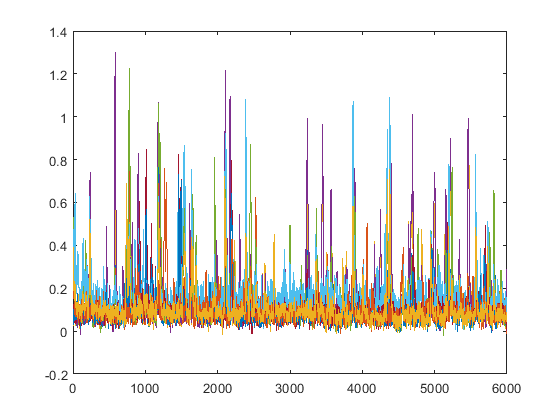

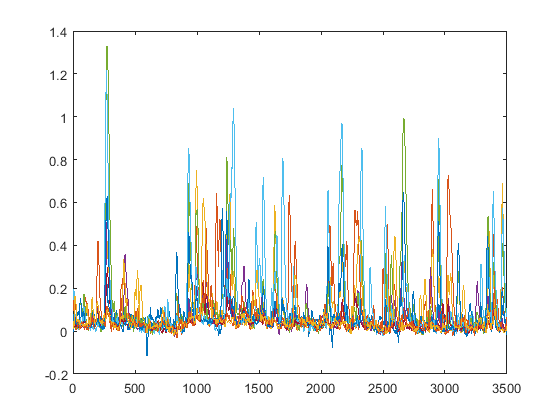

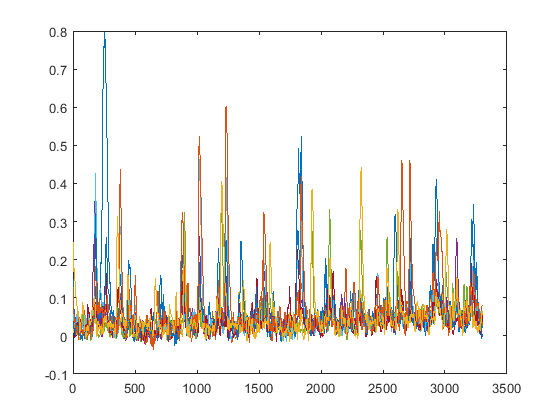

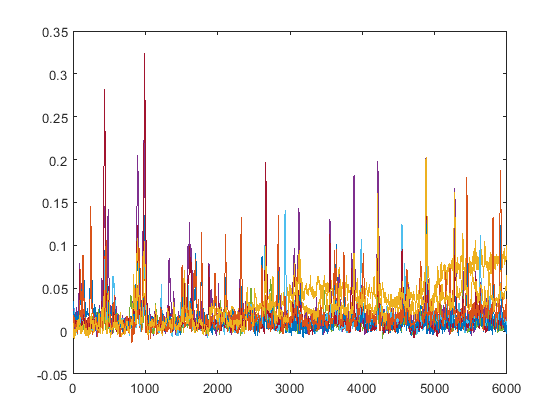

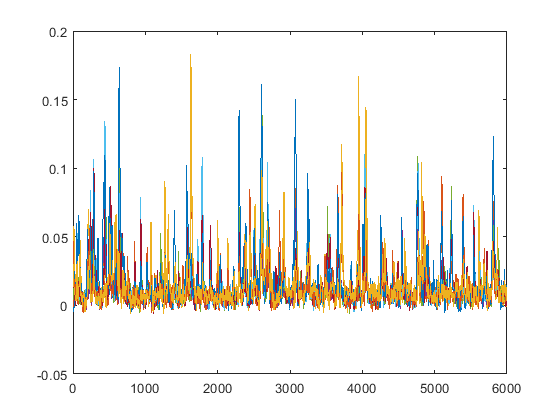

files = loadFileList('.\Data\Snap25GC6s_SR101\*\*ROIs.mat');

[m,n] = size(files);
groupEvents = [];
for i = 1:m
    s = load(files{i});
    fns = fieldnames(s);
    temp = s.(fns{1});
    temp = temp(:,1:2:20);
    fifth = prctile(temp,5,1);
    tempdF = (temp - fifth)./fifth;
    indivEvents = [];
    for j=1:size(tempdF,2)
        tempdF(:,j) = smooth(tempdF(:,j));
        fifth = prctile(tempdF(:,j),60)
        stdTemp = std(tempdF(tempdF(:,j) < fifth,j),[],1)
        meanTemp = mean(tempdF(:,j));
        meanTemp + 3 * stdTemp
        figure;
        [pks, locs] = findpeaks(tempdF(:,j),'MinPeakProminence',meanTemp + 3 * stdTemp,'Annotate','extents');
        indivEvents(j)=size(pks,1);
    end
    groupEvents(i) = mean(indivEvents,2)/(size(tempdF,1)/600);
    plot(tempdF);
end

%Multicolor plot

## reload data

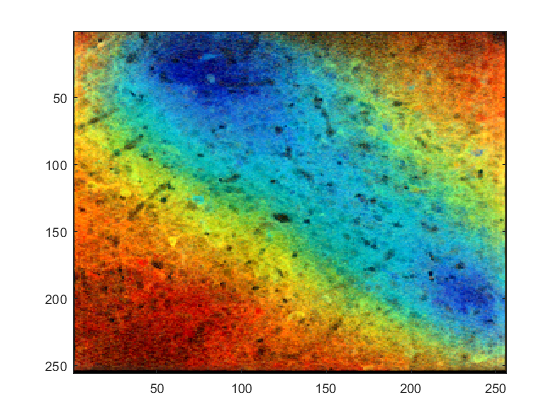

file = '.\Data\Snap25GC6s_SR101\Animal 1_170714_004\2Pcorr.mat';
load(file);
corrImg = data.corrImg;
corrRGB = zeros(256,256,3);
%original
corrRGB(:,:,3) = corrImg(:,:,1)*.8 + corrImg(:,:,3)/max(max(corrImg(:,:,1) + corrImg(:,:,3)));
corrRGB(:,:,2) = (corrImg(:,:,5) + corrImg(:,:,3))/max(max(corrImg(:,:,5) + corrImg(:,:,3)));
corrRGB(:,:,1) = corrImg(:,:,6)/max(max(corrImg(:,:,6)));
%altered
corrRGB(:,:,1) = corrImg(:,:,6) + corrImg(:,:,5)*.5 + corrImg(:,:,4)*1.1;
corrRGB(:,:,2) = corrImg(:,:,4)*.8 + corrImg(:,:,3)*.4 + corrImg(:,:,2)*.7; % )/max(max(corrImg(:,:,5)  ));
corrRGB(:,:,3) = corrImg(:,:,1)*.8 +corrImg(:,:,2)*.7;



figure; imagesc(corrRGB);

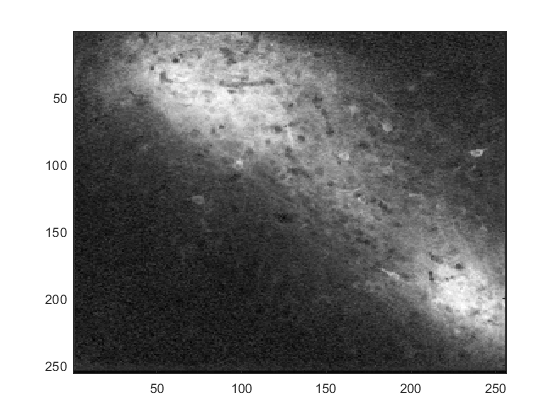

imwrite(corrRGB,['.\Data\ICCorrMap_2p.bmp']);

figure; imagesc(corrImg(:,:,1)); colormap gray;